# Part 4: Population Genetics

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

A rendering of a DNA double [helix](https://commons.wikimedia.org/wiki/File:DNA-Helix-Rendering_20220603.png). 

Now we'll turn to population genetics, or comparing DNA sequence variations within a species. The study of population genetics can tell us how genetic traits change over time in a population and help us determine what shapes genetic diversity in the human population overall. It can also help us predict what types of genetic differences might lead to different diseases.

As an example, the 1000 Genome project contains data from many different human populations across the world. One way to analyze genetic variation in humans is to look at the different [alleles](https://en.wikipedia.org/wiki/Allele) that an individual's DNA contains. Alleles are just alternate versions of a specified gene. So an example might be a gene that determines eye color--there might be a blue eye allele, a brown eye allele, and so on. It makes sense that we can define genetic variation in terms of which alleles of any given gene are present in different human populations. A common form of such variation is a [single nucleotide polymorphism](https://en.wikipedia.org/wiki/Single-nucleotide_polymorphism) (SNP, pronounced "snip"), and this just means that the most common nucleotide in a given position in a gene is sometimes replaced by a different nucleotide at that position. For example: 

You might have a SNP that occurs in position 2 on a chromosome. Let's imagine a very shortened DNA strand for 3 individuals: 

*person 1: ATCGC*

*person 2: AGCGC*

*person 3: ATCGC*

Persons 1 and 3 both have a 'T' in position 2, but person 2 has a 'G'. If we collected the DNA sequence from this chromosome in an entire population, we might find that 80% of people have a 'T' at that position and 20% of people have a 'G'. Position 2 would be the SNP position, and 'T' would be the most commonly occurring allele or nucleotide, while 'G' would be the variant allele. The 1000 genome project considers SNPs that occur in greater than 1% of the population. For simplicity, we will say that there is only one major variant for each SNP position in a population. 

We can store such data in a straightforward way in MATLAB®. We can create a matrix, for example, where each row is a person in our population, and each column is a SNP that might occur in humans. If the individual has the most common nucleotide for any given SNP position (in this example 'T'), the entry in that SNP column will be a 1. If the individual has the variant SNP ('G'), the entry in that column will be a 0. 

## 1: Simulate population data

We will simulate data for this section. There is a function included at the end of this script that simulates the data for us. 

Imagine we have 5 distinct populations of people and we have a matrix of the SNPs for each. The population size (number of rows) will vary for each population, but the number of SNPs (columns) is always 1000. 

Run the simulation function, the only input is the number of populations you want to simulate (5 in this case!): 

[geno, popsize, popname]  =  simulatePopulation(5); 
geno
popsize

We can see that `geno` is a cell array where each input is the simulated data for a single population. The size of each cell is always:

*(number of individuals) x (the 1000 SNPs we are considering)*.

We're also printing out the population size (`popsize`) for each population separately. Also, the function gives us an array of the length of the total number of individuals we have, and each individual has a number that indicates which population they are from. This will help us later when we start plotting.

Let's sci-fi this simulation a little bit and imagine a fictional world hundreds of years in the future. Say we have a group of Northern European people who were living in New York City (population 1). Hundreds of years ago, a group of them got sick of modern society and broke off and moved off-grid to the forest (population 2). It's likely that through selective mutation and genetic drift and isolation, their genome has changed slightly. For example, maybe they've developed the ability to metabolize different plants than the city dwellers. Population 3 is a group of those Northern Europeans who moved to the mountains. Maybe they've developed a genetic resistance to elevation sickness. Say that population 4 is a group of them who got tired of the seasons and moved to the desert. They may have experienced adaptions that allow tolerance to extreme temperatures, such as increased sweat rate. Maybe population 5 is a group of mole people who moved into underground tunnels beneath NYC. Perhaps they have a genetic difference that allows them to see in the dark. All these populations are part of the same species and come from a common ancestor, but there are genetic differences between them. How can we visualize and understand those differences? 

There is an incredible amount of data here- 5 populations, 1000 SNP locations, and around 1000 individuals per population. Let's look at the data contained in the first cell of `geno`. 

  Type `geno{1} `in the code block:

It's all just a bunch of 1s and 0s to me! We need to figure out the best way to look at this data so it's comprehensible.  Luckily, we can utilize MATLAB tools to understand this data. 

It helps to concatenate or combine all of our data into one matrix first, for numerical analyses. We are just making one big matrix of all of our populations: 

genotypes = vertcat(geno{1}, geno{2}, geno{3}, geno{4}, geno{5});

So the number of rows in genotypes is now the sum of all individuals (everyone is represented in this one matrix), and columns remain the same, with 1 for each of the 1000 possible SNP locations. Note that the results will be different here each time you re-simulate the data! Let's check out what I got when I simulated the data: 

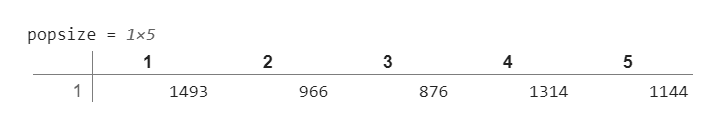

So in genotypes in this case, rows 1:1493 are individuals from population 1, the next 966 rows are from population 2, the next 876 individuals are from population 3, and so on. 

## 2: Visualize differences in genomes between populations

One thing we can try is visualizing what these SNP variations look like! Use [`imagesc()`](https://www.mathworks.com/help/matlab/ref/imagesc.html), which allows us to display a matrix as an image. All we need to know is that 1s and 0s in our matrix will get different colors in the figure. 

  Type `imagesc(genotypes)` and run the section: 

Add x and y labels for clarity: 

xlabel("1000 shared SNP markers on a single chromosome")
ylabel("Individual")

In my simulated data, I got: 

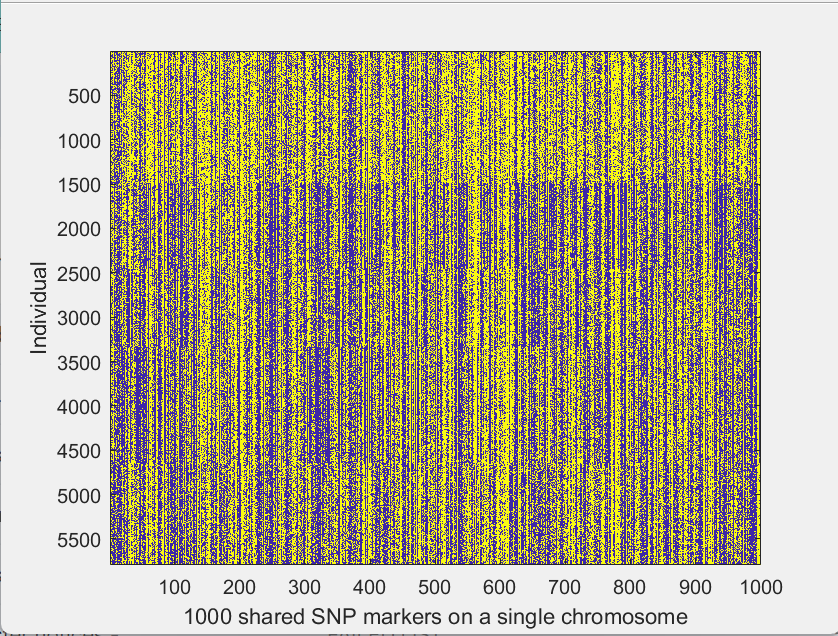

This is showing at each SNP position (x-axis) which allele the individual has (for example: perhaps in SNP 400 the common/reference nucleotide is A, and the mutation that occurs in a portion of the population is G, individuals with a yellow dot have an A at SNP position 400, and individuals with a blue dot have the G instead). 

 Can you visualize the different populations in this plot? 

You can see how the first 1493 individuals have a similar profile, and this corresponds to population 1 (there is of course some within-population variation, but not as much as between populations!). You can see the 5 separate populations here. 

 While these are 5 simulated and fictional populations, examples of [different populations included](https://www.internationalgenome.org/data-portal/population) in the 1000 genome project are Finnish in Finland, Japanese in Tokyo (Japan), Gujarati Indians in Houston (Texas), Puerto Rican in Puerto Rico, and more! Check out the linked international genome project page to learn more. 

## 3: Group populations based on similarities/differences of their SNP variations

A commonly used 'real world' analysis method for large datasets is [dimensionality reduction](https://en.wikipedia.org/wiki/Dimensionality_reduction). It's pretty impossible to plot and make sense of a matrix that is as large as 5000x1000. What we can do is decrease the number of dimensions we use to visualize the data. There's a method called [Principal Component Analysis, or PCA](https://en.wikipedia.org/wiki/Principal_component_analysis), that does this for us. You can think of it just as a built-in method that allows you to visualize biological data that has a lot of dimensions, but if you're interested, you can find more information about PCA in the Machine Learning Module***(add link to module 6 File Exchange)*** from this series. 

Use the function[ `pca()`](https://www.mathworks.com/help/stats/pca.html) on `genotypes`: 

[~,s] = pca(genotypes); 

This has changed the dimensions of our data in some way, and the data has been shifted to new dimensions that best explain the data! The first two columns of our output s should be enough to explain the data (dimension 1 and dimension 2). Let's plot those first two columns (plot all rows, so all  people are still included) of s: 

scatter(s(:,1), s(:,2)) %scatter plot all rows, but only the first two columns, of x 

  Add an x-label titled *Dimension 1* using `xlabel('Dimension 1')`:

  Add a y-label for *Dimension 2*: 

You can start to see that some populations are close together, and some are further apart! But what if we want to visualize this and sort by population (i.e. make each population a different color)? 

Recall [`gscatter()`](https://www.mathworks.com/help/stats/gscatter.html) from the biosciences data module. We can plot dimensions 1 and 2 of `s`, and group the points by their population name, `popname`.

gscatter(s(:,1), s(:,2), popname); 

  Add x and y labels as above: 

We'll also add a legend so we can see which population is which: 

legend ("NYC", "Forest", "Mountain", "Desert", "Mole") 

 What do you notice here? What does it mean when some populations are more overlapping than others? Which populations are most different here? Compare the overlap you see here to the similarities of each population in the `imagesc()` plot. 

In my example simulation I got the following plots: 

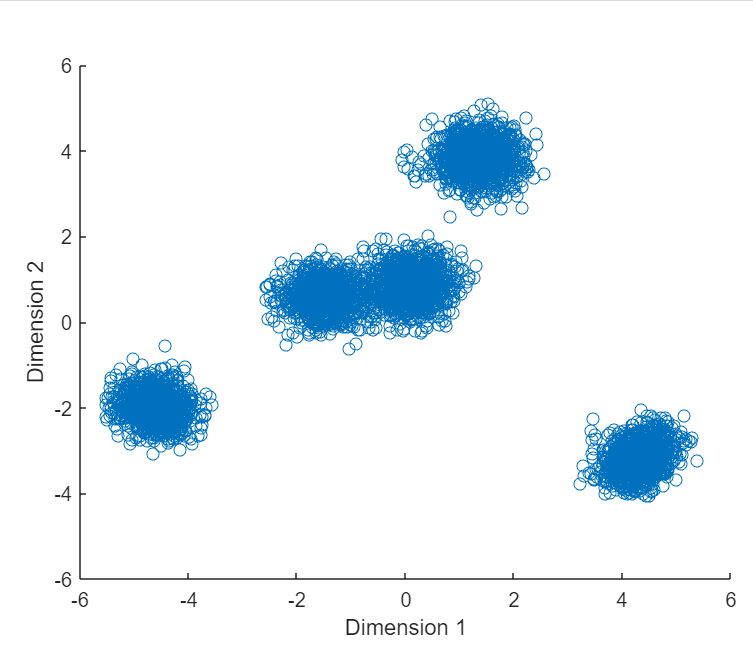  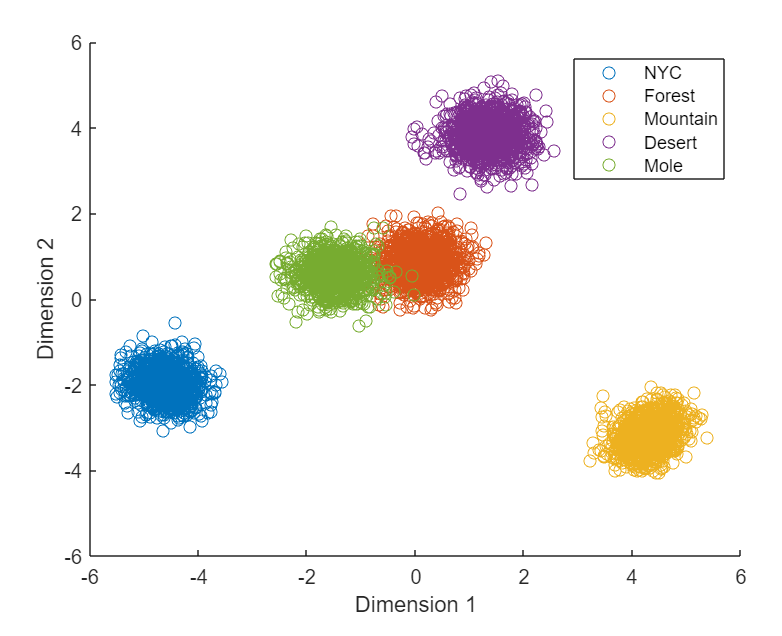

You can see how the 5 original populations make up the original plot! The Forest population and the Mole population are the most genetically similar in this example, with other populations appearing more distinct. This means that the evolutionary pressure faced by the forest and mole populations is the most similar. Maybe they both have to see in the dark, or adapt to digesting similar food sources! Remember that your population data will change each time the simulation runs-this is just a toy example! 

In this section, we've learned how to visualize genetic differences between populations using dimensionality reduction. Complete the problem set section for further practice!

[*Go to next section (Problem set)*](matlab: edit S5_Problem_set.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

## Helper Function: 

This function simulates SNP data for the number of populations you provide as input: 

function [genoArray, numPop, nameofPop] = simulatePopulation(pops)

Imagine for the chromosome that we are looking at there are 1000 possible SNPs. We will first make one 'base' human genome with a value at each of those 1000 SNP positions, called `alleleFreq. `This value gives the frequency of variation at that SNP in this population. For simplicity, the SNP value can either be 1 or 0, meaning there are only two possible nucleotides that could exist at that position. Because any given percentage of the population will have a variation at each SNP in the population, we use `rand` to randomly assign a percentage of the population to each SNP`:`

    numSNP = 1000; 
    alleleFreq = rand(numSNP, 1); 
    genoArray = {};

Now, we will loop through each population. First, we choose a random value between 750 and 1500 as population size. For this population, we will pick 100-200 random SNP positions that will have a different frequency than the standard human genome `alleleFreq`. We'll take `alleleFreq`, and in those positions, we'll give this population a new different frequency of the SNP occurrence (basically the "base" genome is the same, but we're adding different SNP frequencies at a random set of 100-200 positions on the chromosome).

    for i = 1:pops
        numPeople = randi([750 1500],1); 
        pop2perm = randperm(numSNP, randi([100 200],1));
        alleleFreqNEW = alleleFreq; 
        alleleFreqNEW(pop2perm) = rand(1); 

Next, we make a matrix size `numPeople` x `numSNP` that fills with 1s or 0s as described based on the calculated allele frequencies across the population: 

        genotype(1:numPeople,1:1000,i) = binornd(1, repmat(alleleFreqNEW', numPeople, 1));        

For our analyses, we output the number of people in each population from the function, as well as the genome for each population: 

        numPop(i) = numPeople; 
        genoArray{i} = genotype(1:numPeople,:,i); 
    end % population for loop ends 

To use dimensionality reduction methods, we will eventually need to concatenate all people from all populations together (we do this outside the loop). Once we have one big matrix of all SNPs with all individuals, we will need a way to say which population each individual is from. So, we make an array of the population each individual is a part of, `nameofPop`: 

    ids = [0 cumsum(numPop)]; 
    nameofPop = NaN(1,max(ids)); 

    for i = 1:pops
        nameofPop(ids(i)+1:ids(i+1)) = i;  
    end

end % end function 